This Matlab code is used for demonstration of the effect of CDF-TS as a preprocessing method to transform data. 

For details, please refer to the Pattern Recognition paper: CDF Transform-and-Shift: An effective way to deal with datasets of inhomogeneous cluster densities

Written by Ye Zhu, Deakin University, April 2021, version 1.0. This software is under GNU General Public License version 3.0 (GPLv3).

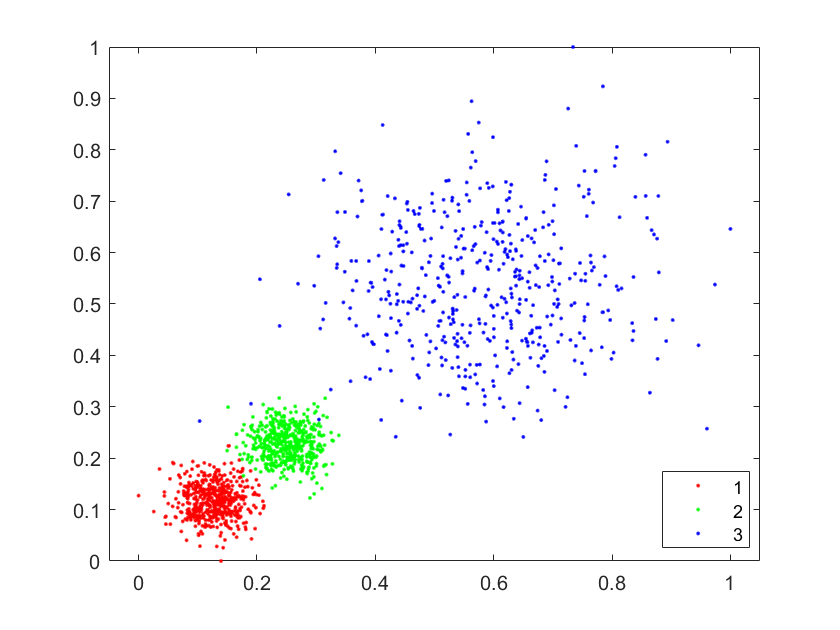

% load and visualise the original data
load('syn.mat')
gscatter(data(:,1),data(:,2),class)

% rescale and visualise the transformed data
eta=0.1;
thre=0.2;
[ ndata ] = CDF_TS( data,eta,thre );

Total iteration time is 1


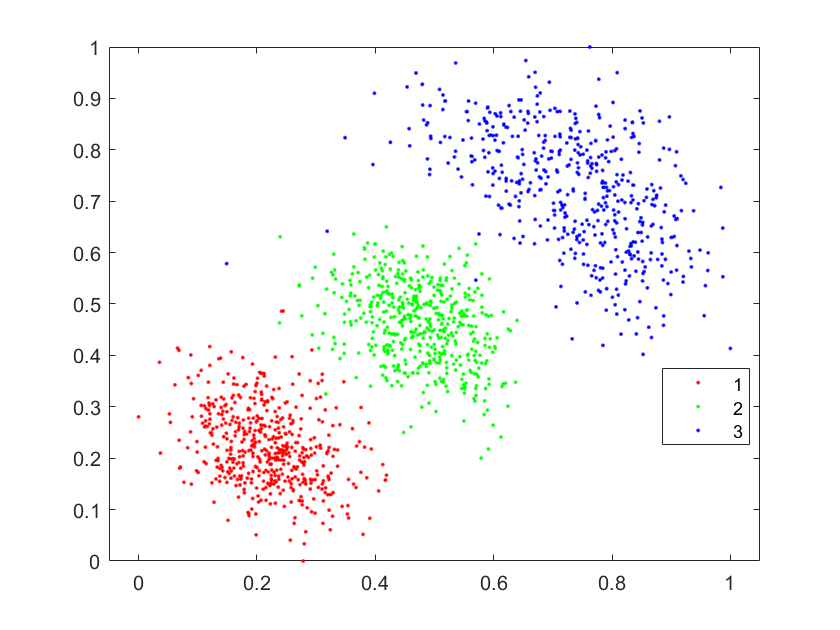

gscatter(ndata(:,1),ndata(:,2),class)

% reduce the thre to increase iterations and obtain more uniformly distributed data
eta=0.1;
thre=0.01;
[ ndata ] = CDF_TS( data,eta,thre );

Total iteration time is 5


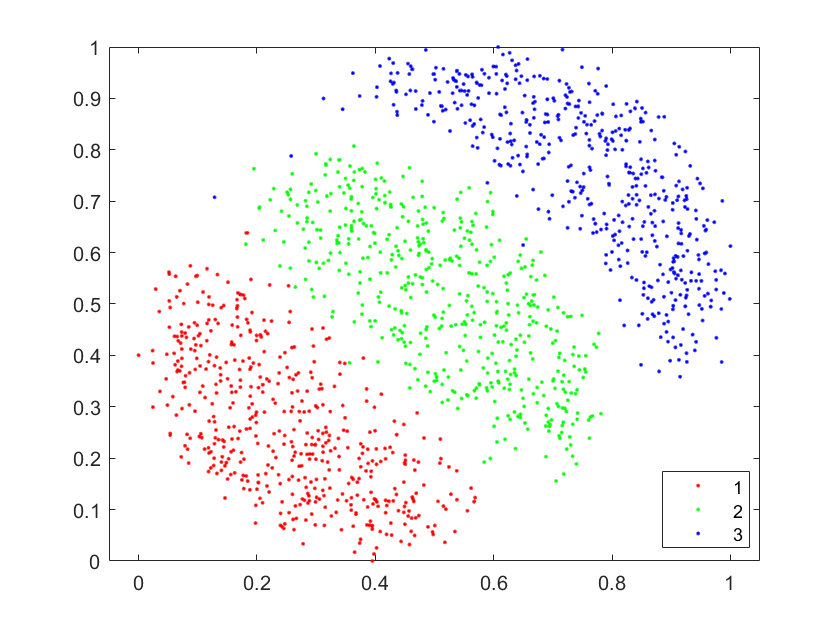

gscatter(ndata(:,1),ndata(:,2),class)